# Import data from text file

Script for importing data from the following text file:

Auto-generated by MATLAB on 26-Nov-2024 17:36:38

## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 14);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = "\t";

% Specify column names and types
opts.VariableNames = ["Time", "LE", "F4", "C4", "P4", "P3", "C3", "F3", "Trigger", "Time_Offset", "ADC_Status", "ADC_Sequence", "Event", "Comments"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "char"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Comments", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Comments", "EmptyFieldRule", "auto");

% Import the data
WFR3 = readtable("/Users/gayatrimalladi/Desktop/untitled folder/Prof_Mat_pre_stroke/W_F_R_3.txt", opts)

WFR3 = 18869×14 table
     Time      LE        F4        C4       P4       P3       C3        F3       Trigger    Time_Offset    ADC_Status    ADC_Sequence    Event     Comments 
    ______    _____    _______    _____    _____    _____    _____    _______    _______    ___________    __________    ____________    _____    __________

    0.0033    -67.9      377.4    -60.2    -55.6    -27.6    -12.7      234.1       0            6             0             195           1      {' Rest '}
    0.0067    164.4     -834.5

## Clear temporary variables

clear opts
% Extract EEG channels
eeg_channels = WFR3{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};

% Check for NaN or Inf in the EEG channels
if any(~isfinite(eeg_channels(:)))
    eeg_channels(~isfinite(eeg_channels)) = 0; % Replace non-finite values with zeros
end

% Define sampling frequency and channel names
sfreq = 300; % Sampling frequency in Hz
ch_names = {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}; % Channel names

% Apply notch filter to remove powerline noise
notch_freqs = [50, 60]; % Frequencies to remove
for i = 1:length(notch_freqs)
    d = designfilt('bandstopiir', 'FilterOrder', 2, ...
        'HalfPowerFrequency1', notch_freqs(i) - 1, ...
        'HalfPowerFrequency2', notch_freqs(i) + 1, ...
        'SampleRate', sfreq);
    eeg_channels = filtfilt(d, eeg_channels); % Apply filter
end

% Define bandpass filter parameters
low_freq = 7;  % Lower cutoff frequency (Hz)
high_freq = 14; % Upper cutoff frequency (Hz)

% Design a bandpass filter
[b, a] = butter(4, [low_freq high_freq] / (sfreq / 2), 'bandpass');

% Apply the bandpass filter to the EEG data
filtered_data = filtfilt(b, a, eeg_channels);

% Display a summary of the filtered data
disp('Filtered EEG data:');

Filtered EEG data:


disp(filtered_data);

   1.0e+03 *

   -0.0005    0.0007    0.0003   -0.0012    0.0008    0.0000    0.0004
    0.0437   -0.2315    0.0378    0.0342    0.0188    0.0069   -0.1432
    0.0856   -0.4516    0.0734    0.0678    0.0359    0.0135   -0.2792
    0.1230   -0.6483    0.1052    0.0979    0.0512    0.0195   -0.4008
    0.1543   -0.8120    0.1317    0.1229    0.0639    0.0245   -0.5019
    0.1778   -0.9348    0.1516    0.1417    0.0735    0.0285   -0.5777
    0.1926   -1.0114    0.1640    0.1536    0.0794    0.0311   -0.6249
    0.1981   -1.0392    0.1686    0.1580    0.0816    0.0324   -0.6419
    0.1944   -1.0182    0.1652    0.1550    0.0800    0.0322   -0.6288
    0.1820   -0.9513    0.1545    0.1451    0.0748    0.0307   -0.5873
    0.1619   -0.8437    0.1372    0.1289    0.0664    0.0280   -0.5206
    0.1354   -0.7027    0.1144    0.1077    0.0554    0.0242   -0.4333
    0.1041   -0.5368    0.0877    0.0827    0.0424    0.0195   -0.3306
    0.0700   -0.3559    0.0584    0.0554    0.0282    0.0143   


% Compute statistics
stats.mean = mean(eeg_channels, 1); % Mean
stats.variance = var(eeg_channels, 0, 1); % Variance
stats.std_dev = std(eeg_channels, 0, 1); % Standard Deviation
stats.median = median(eeg_channels, 1); % Median
stats.min = min(eeg_channels, [], 1); % Minimum
stats.max = max(eeg_channels, [], 1); % Maximum

% Display statistics
disp('Statistics for EEG Channels:');

Statistics for EEG Channels:


disp(array2table([stats.mean; stats.variance; stats.std_dev; stats.median; stats.min; stats.max], ...
    'VariableNames', ["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
    'RowNames', {'Mean', 'Variance', 'StdDev', 'Median', 'Min', 'Max'}));

                   LE         F4          C4          P4          P3          C3         F3   
                ________    _______    ________    ________    ________    ________    _______

    Mean         0.49613    -10.963    -0.96599    -0.70957    -0.23389    -0.25443    -2.1445
    Variance      254.68       5443      266.42      192.63      84.883       66.16     2173.3
    StdDev        15.959     73.777      16.322      13.879      9.2132      8.1339     46.619
    Median      0.015525    -5.3207     -1.2429     -1.1229    -0.52489    -0.28908    0.82864
    Min          -66.934    -2257.1     -115.64     -58.661     -61.556      -31.02    -1398.5
    

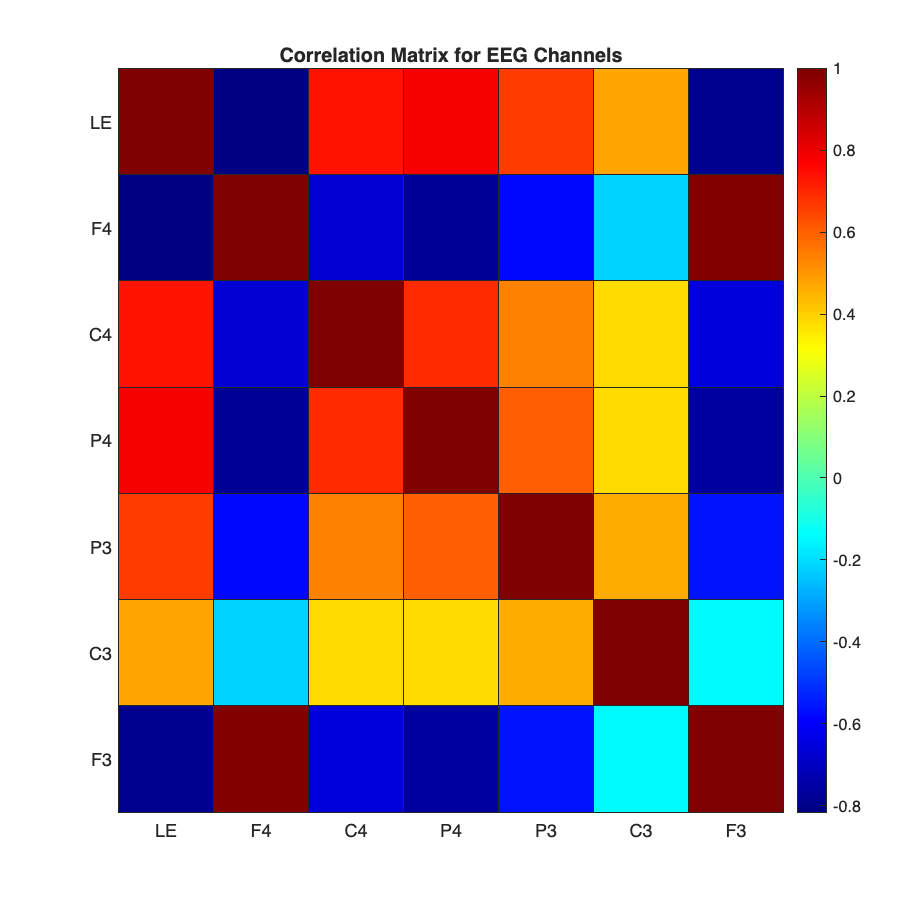


% Compute the correlation matrix
correlation_matrix = corr(eeg_channels);

% Plot correlation matrix as heatmap
figure('Name', 'EEG Correlation Matrix', 'Position', [100, 100, 800, 800]);
heatmap(["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
        ["LE", "F4", "C4", "P4", "P3", "C3", "F3"], ...
        correlation_matrix, ...
        'Colormap', jet, ...
        'ColorbarVisible', 'on', ...
        'CellLabelColor', 'none'); % Optional to hide correlation labels
title('Correlation Matrix for EEG Channels');

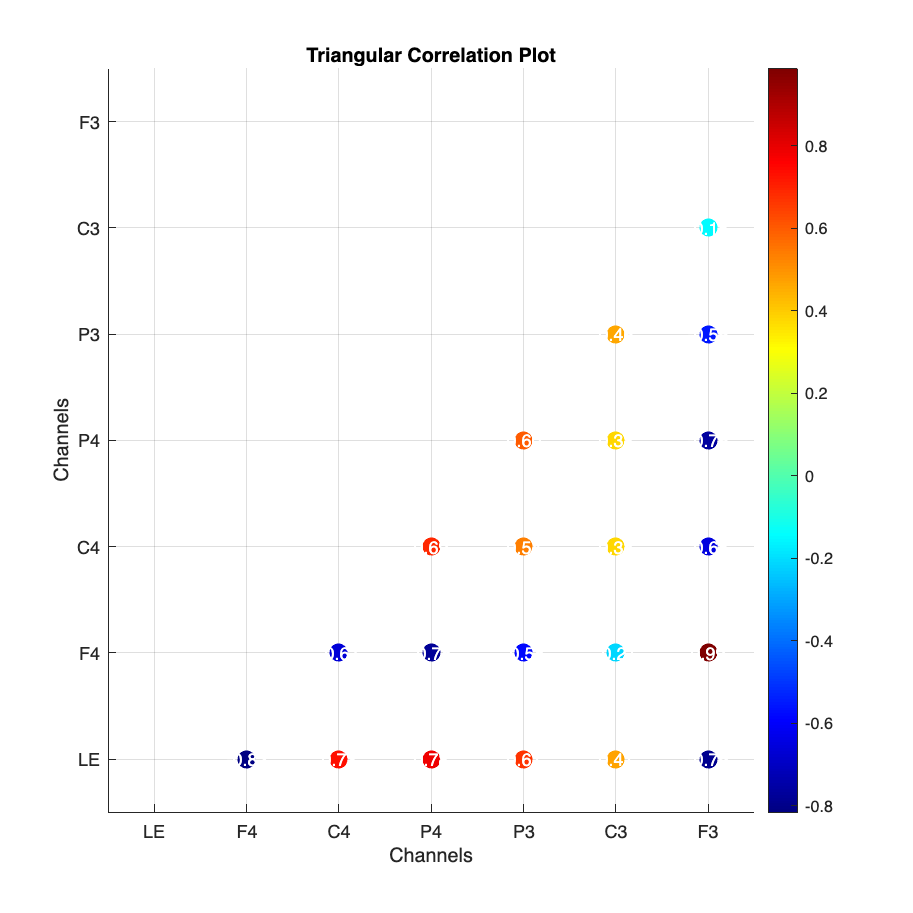


% Generate correlation plot
figure('Name', 'Triangular Correlation Plot', 'Position', [100, 100, 800, 800]);
hold on;
n_channels = size(correlation_matrix, 1);
for i = 1:n_channels
    for j = 1:i
        if i ~= j
            scatter(i, j, 100, correlation_matrix(i, j), 'filled');
            text(i, j, sprintf('%.2f', correlation_matrix(i, j)), ...
                'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', 'Color', 'w');
        end
    end
end
colormap(jet);
colorbar;
xlim([0.5, n_channels + 0.5]);
ylim([0.5, n_channels + 0.5]);
xticks(1:n_channels);
yticks(1:n_channels);
xticklabels(["LE", "F4", "C4", "P4", "P3", "C3", "F3"]);
yticklabels(["LE", "F4", "C4", "P4", "P3", "C3", "F3"]);
xlabel('Channels');
ylabel('Channels');
title('Triangular Correlation Plot');
grid on;
hold off;

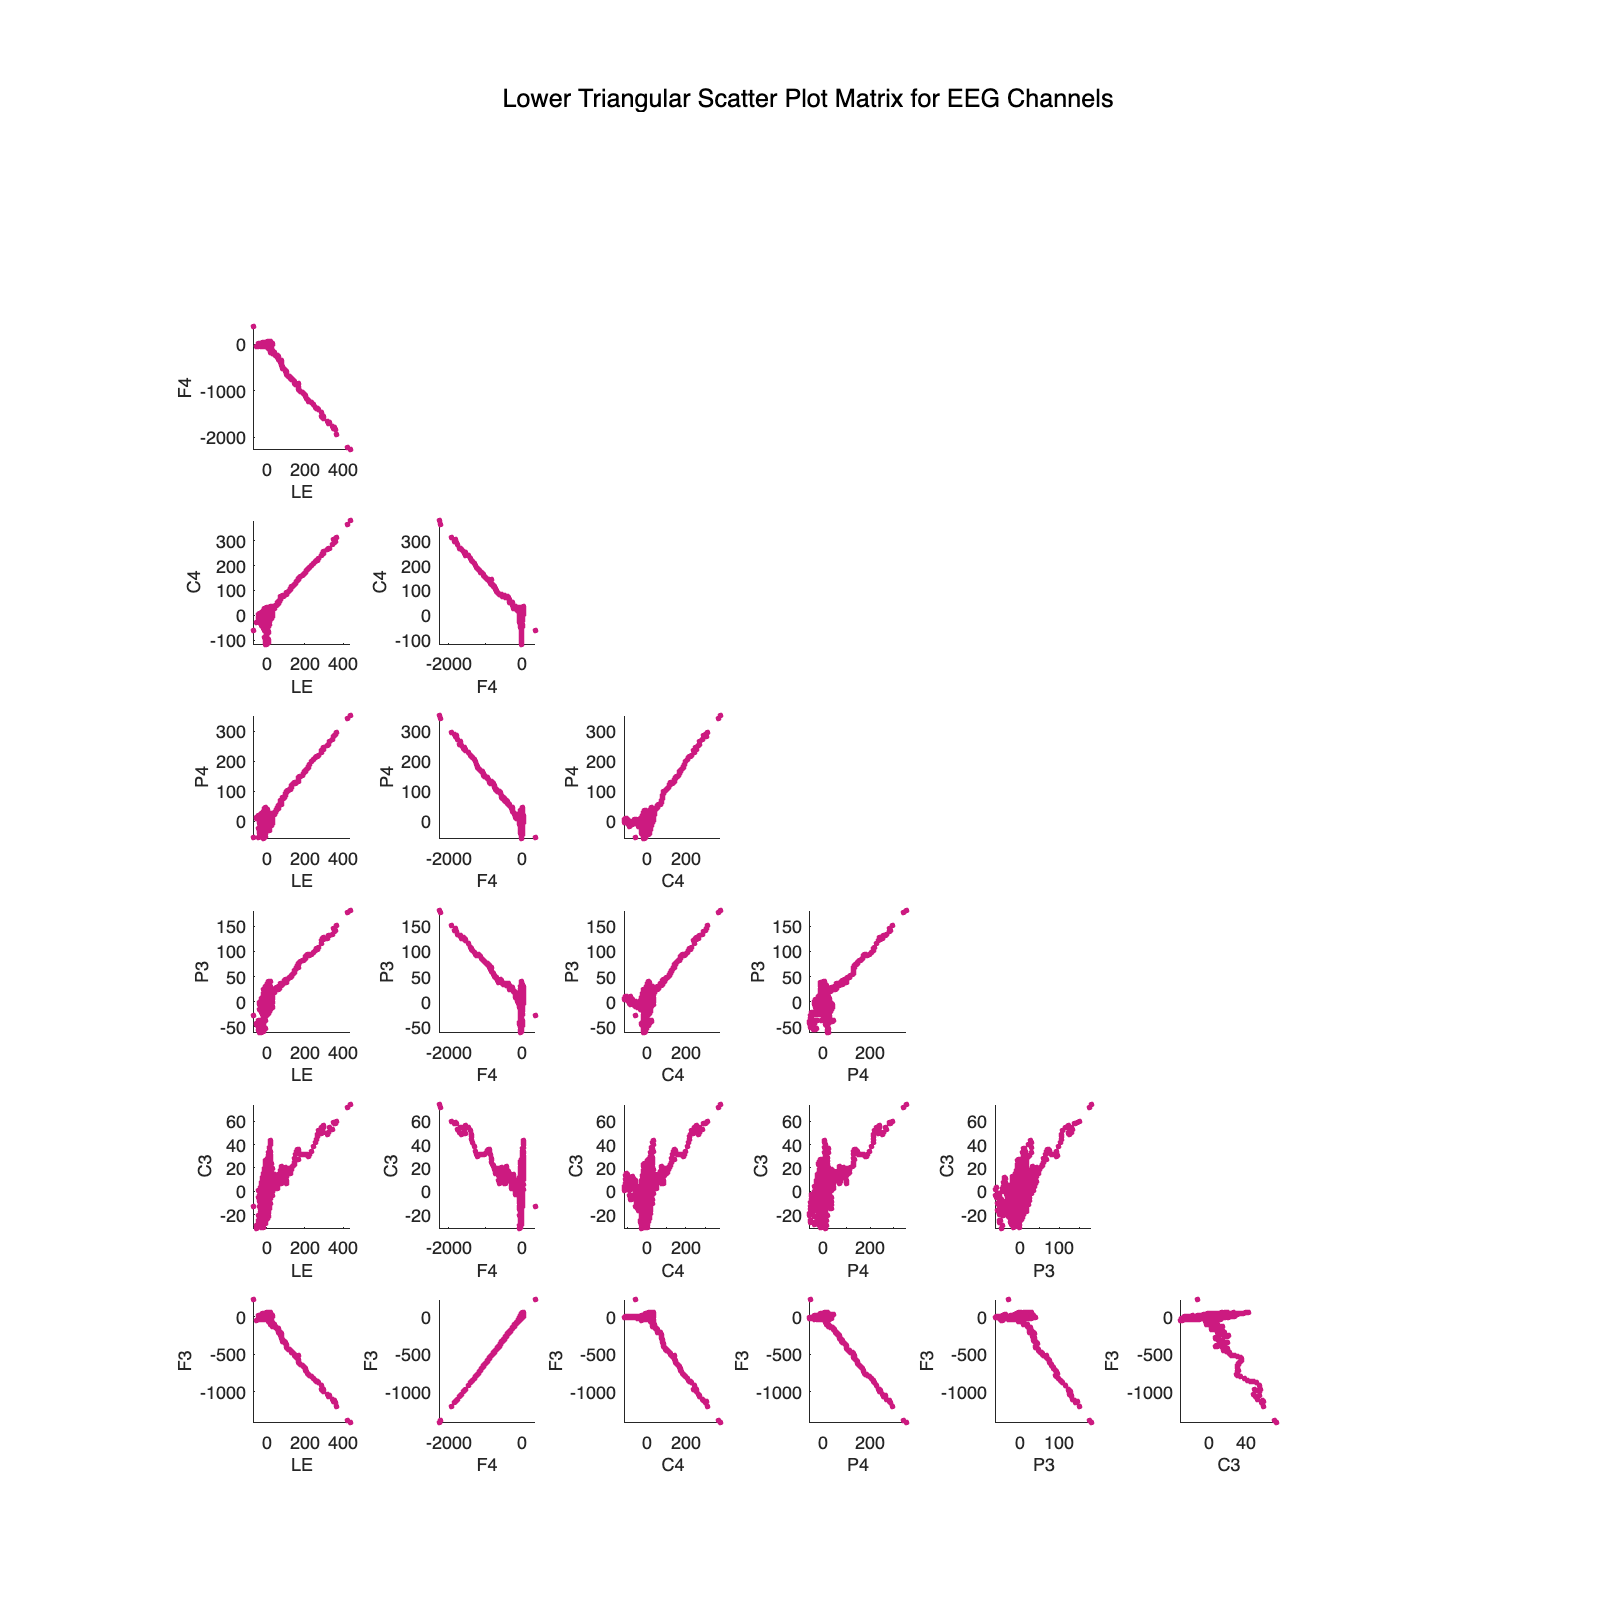

% Extract relevant variables from WFR3
% Extract EEG channels and channel names
eeg_channels = WFR3{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};
channel_names = ["LE", "F4", "C4", "P4", "P3", "C3", "F3"];
num_channels = size(eeg_channels, 2);

% Create figure for scatter plot matrix
figure('Name', 'Scatter Plot Matrix for EEG-1 Channels', 'Position', [100, 100, 1000, 1000]);

for i = 2:num_channels
    for j = 1:i-1
        % Plot the scatter plot with dark pink dots
        subplot(num_channels, num_channels, (i-1) * num_channels + j);
        scatter(eeg_channels(:, j), eeg_channels(:, i), 10, [0.8, 0.1, 0.5], 'filled'); % Dark pink color for dots
        xlabel(channel_names(j), 'FontSize', 10);
        ylabel(channel_names(i), 'FontSize', 10);
        xlim([min(eeg_channels(:, j)) max(eeg_channels(:, j))]);
        ylim([min(eeg_channels(:, i)) max(eeg_channels(:, i))]);
    end
end

% Remove upper triangle subplots to create lower triangular matrix
for i = 1:num_channels
    for j = i:num_channels
        subplot(num_channels, num_channels, (i-1) * num_channels + j);
        axis off;
    end
end

% Title for the scatter plot matrix
sgtitle('Lower Triangular Scatter Plot Matrix for EEG Channels', 'FontSize', 14);


% Read additional data from another file
data = readtable("/Users/gayatrimalladi/Desktop/untitled folder/Prof_Mat_pre_stroke/W_F_R_3.txt"); 

% Extract EEG channels and time from the new data
eeg_channels = data{:, {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}};
time = data{:, 'Time'};


% Extract EEG channels
eeg_channels = WFR3{:, ["LE", "F4", "C4", "P4", "P3", "C3", "F3"]};

% 1. Zero Crossing Rate
zero_crossing_rate = sum(diff(sign(eeg_channels)) ~= 0, 1) / size(eeg_channels, 1);
disp(zero_crossing_rate)

    0.1150    0.0667    0.0696    0.0910    0.0864    0.1129    0.0938




% 2. Skewness
skewness_val = skewness(eeg_channels, 0, 1);
disp(skewness_val)

   12.0364  -18.0226    6.5012   10.1307    4.1607    0.4615  -17.5430




% 3. Kurtosis
kurtosis_val = kurtosis(eeg_channels, 0, 1);
disp(kurtosis_val)

  231.8967  383.4501  115.7849  181.3018   63.9937    5.9339  368.1629



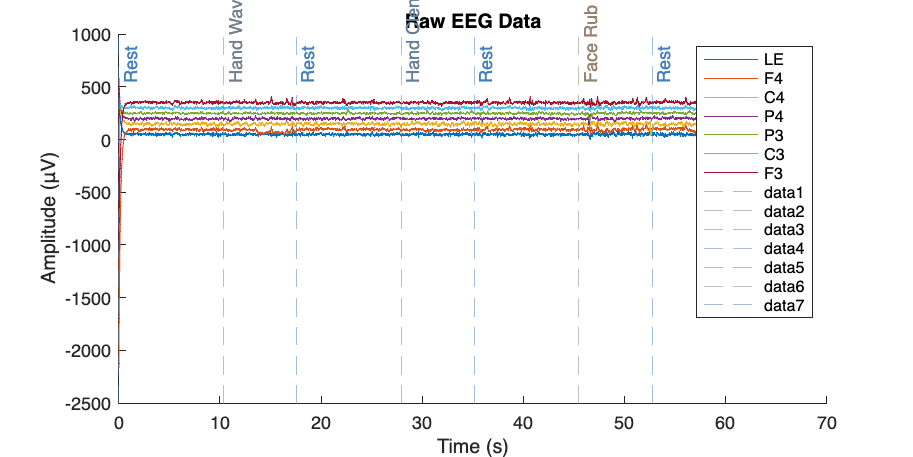

% Extract relevant data
time = data.Time; 
comments = data.Comments; 
eeg_channels = data{:, {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}}; % EEG channels
ch_names = {'LE', 'F4', 'C4', 'P4', 'P3', 'C3', 'F3'}; % Channel names
sfreq = 300; % Sampling frequency
% Step 1: Parse comments and timestamps
comment_timestamps = [];
comment_names = {};
for i = 1:height(data)
    if ischar(data.Comments{i}) && ~isempty(strtrim(data.Comments{i}))
        comment_timestamps(end+1) = data.Time(i); % Add timestamp
        comment_names{end+1} = data.Comments{i}; % Add comment
    end
end
% Step 2: Generate a color for each comment
hash = @(str) mod(sum(double(str) .* (1:length(str))), 256); % Simple hash function
name_to_color = @(name) [hash(name)/255, 0.5, 1 - hash(name)/255]; % Generate RGB colors
% Step 3: Plot raw EEG data
figure('Name', 'Raw EEG Data', 'Position', [100, 100, 1000, 500]);
colors = lines(length(ch_names)); % Define colors for channels

hold on;
for i = 1:size(eeg_channels, 2)
    plot(time, eeg_channels(:, i) + i * 50, 'Color', colors(i, :), 'DisplayName', ch_names{i}); % Offset each channel for clarity
end
% Add vertical lines and labels for comments
for i = 1:length(comment_timestamps)
    comment_color = name_to_color(comment_names{i});
    xline(comment_timestamps(i), '--', 'Color', comment_color, 'Alpha', 0.5);
    text(comment_timestamps(i), max(max(eeg_channels)) + 100, comment_names{i}, ...
        'Rotation', 90, 'VerticalAlignment', 'top', 'Color', comment_color);
end

title('Raw EEG Data');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend('show');
hold off;

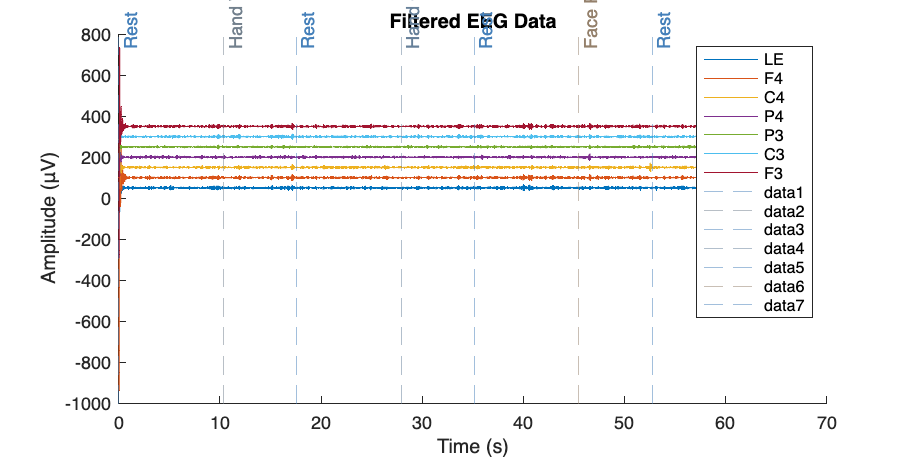

% Step 4: Apply filters (notch and bandpass)
notch_freqs = [50, 60];
for f = notch_freqs
    d = designfilt('bandstopiir', 'FilterOrder', 2, ...
        'HalfPowerFrequency1', f - 1, ...
        'HalfPowerFrequency2', f + 1, ...
        'SampleRate', sfreq);
    eeg_channels = filtfilt(d, eeg_channels); % Apply notch filter
end
% Bandpass filter
low_freq = 7; high_freq = 14;
[b, a] = butter(4, [low_freq high_freq] / (sfreq / 2), 'bandpass');
filtered_data = filtfilt(b, a, eeg_channels);
% Step 5: Plot filtered EEG data
figure('Name', 'Filtered EEG Data', 'Position', [100, 100, 1000, 500]);
hold on;
for i = 1:size(filtered_data, 2)
    plot(time, filtered_data(:, i) + i * 50, 'Color', colors(i, :), 'DisplayName', ch_names{i}); % Offset each channel
end
% Add vertical lines and labels for comments
for i = 1:length(comment_timestamps)
    comment_color = name_to_color(comment_names{i});
    xline(comment_timestamps(i), '--', 'Color', comment_color, 'Alpha', 0.5);
    text(comment_timestamps(i), max(max(filtered_data)) + 100, comment_names{i}, ...
        'Rotation', 90, 'VerticalAlignment', 'top', 'Color', comment_color);
end
title('Filtered EEG Data');
xlabel('Time (s)');
ylabel('Amplitude (μV)');
legend('show');
hold off;

% Step 6: Time-frequency analysis using wavelet transform
frequencies = 1:80; % Frequencies of interest
n_cycles = frequencies / 2; % Number of cycles in the wavelet
time_range = 1:length(time) / sfreq;
% Morlet wavelet analysis
[power_raw, ~] = cwt(eeg_channels(:, 1), sfreq, 'FrequencyLimits', [min(frequencies) max(frequencies)]); % Example on channel 1
[power_filtered, ~] = cwt(filtered_data(:, 1), sfreq, 'FrequencyLimits', [min(frequencies) max(frequencies)]); % Example on channel 1
% Plot time-frequency analysis for raw data
figure('Name', 'Time-Frequency Analysis (Raw)', 'Position', [100, 100, 1000, 500]);
